# Process Identification of an ARX Model

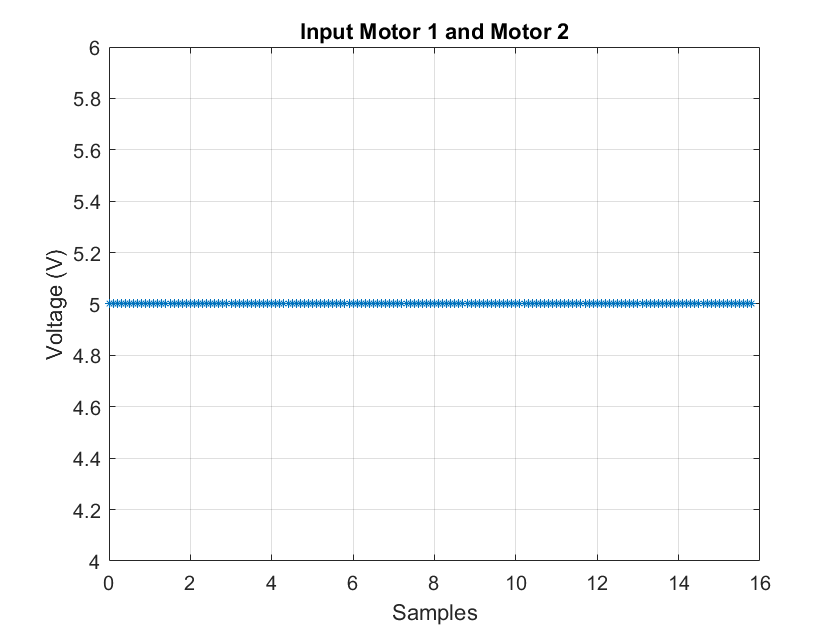

%Data
Data = xlsread("C:\Users\rodri\Documents\PY4E\Control\Reto_Control\Motor_Data\STEP_datos_excel.xlsx");

t = Data(:,1);
U = Data(:,2);
Y1 = Data(:,5);
Y2 = Data(:,6);

% Input
plot(t,U,'*','MarkerSize',4);
title('Input Motor 1 and Motor 2');
ylabel('Voltage (V)');
xlabel('Samples');
grid on

% Red circle Output Motor 1
hold on

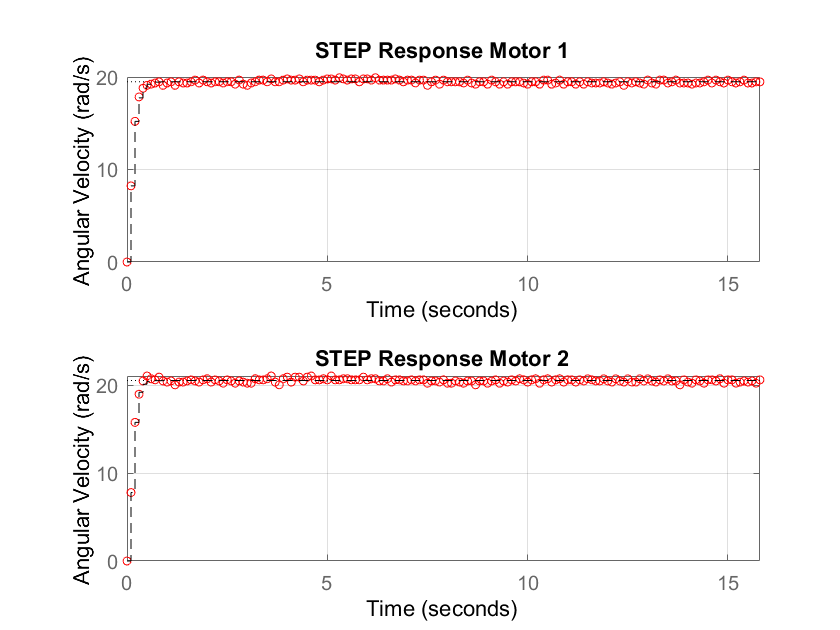

subplot(2,1,1);
plot(t,Y1,'o r', 'MarkerSize', 4);
ylabel('Output Variable');
xlabel('Samples');
grid on

N = length(Y1);

%
X=[-[0;Y1(1:N-1)], -[0;0;Y1(1:N-2)], [0;U(1:N-1)],[0;0;U(1:N-2)], [0;0;0;U(1:N-3)]];

%Covariance Matrix
Q = X'*X;

%Vector of parameters
Theta = inv(Q)*X'*Y1;

a1 = Theta(1);
a2 = Theta(2);
b0 = Theta(3);
b1 = Theta(4);
b2 = Theta(5);

z = tf('z', 0.1);
Gpz_1 = ((b0*z^(2)+b1*z+b2)/(z^2+a1*z+a2))*z^(-1);

% Red Circle Output Motor 2
hold on
subplot(2,1,2);
plot(t,Y2,'o r', 'MarkerSize', 4);
ylabel('Output Variable');
xlabel('Samples');
grid on

N = length(Y2);

%
X=[-[0;Y2(1:N-1)], -[0;0;Y2(1:N-2)], [0;U(1:N-1)],[0;0;U(1:N-2)], [0;0;0;U(1:N-3)]];

%Covariance Matrix
Q = X'*X;

%Vector of parameters
Theta = inv(Q)*X'*Y2;

a1 = Theta(1);
a2 = Theta(2);
b0 = Theta(3);
b1 = Theta(4);
b2 = Theta(5);

z = tf('z', 0.1);
Gpz_2 = ((b0*z^(2)+b1*z+b2)/(z^2+a1*z+a2))*z^(-1);

%Results

hold on
subplot(2,1,1);
step(Gpz_1*(5),'k--',15.8)
title('STEP Response Motor 1')
ylabel('Angular Velocity (rad/s)');
Ymodel1=step(Gpz_1*(5),15.8);
grid on

hold on
subplot(2,1,2);
step(Gpz_2*(5),'k--',15.8)
title('STEP Response Motor 2')
ylabel('Angular Velocity (rad/s)');
Ymodel2=step(Gpz_2*(5),15.8);
grid on


%Covariance in the measurments Motor 1
fprintf('\n')
fprintf('\n Motor 1:')


 Motor 1:

Gpz_1

Gpz_1 =
 
  1.646 z^2 + 1.078 z + 0.1029
  ----------------------------
  z^3 - 0.1925 z^2 - 0.08214 z
 
Sample time: 0.1 seconds
Discrete-time transfer function.



Sy_1 = sum((Y1-mean(Y1)).^2)

Sy_1 = 524.2824

Sr_1 = sum((Y1-Ymodel1).^2)

Sr_1 = 5.1630

R2_1 = (Sy_1 - Sr_1)/Sy_1

R2_1 = 0.9902


%Covariance in the measurments Motor 2
fprintf('\n')
fprintf('\n Motor 2:')


 Motor 2:

Gpz_2

Gpz_2 =
 
  1.558 z^2 + 1.322 z + 0.345
  ----------------------------
  z^3 - 0.1756 z^2 - 0.03887 z
 
Sample time: 0.1 seconds
Discrete-time transfer function.



Sy_2 = sum((Y2-mean(Y2)).^2)

Sy_2 = 605.1802

Sr_2 = sum((Y2-Ymodel2).^2)

Sr_2 = 6.7337

R2_2 = (Sy_2 - Sr_2)/Sy_2

R2_2 = 0.9889